# LAB 3: EIGENVALUE PROBLEM AND ORDINARY DIFFERENTIAL EQUATION

%---------------------------------------
% Fill in your group number.
GroupNumber = 50;
% Fill in your student Name and ID.
Students(1).Name = 'Connor Michaud';
Students(1).ID = '261140414';
Students(2).Name = '';
Students(2).ID = '';
%---------------------------------------

## **0. Objective**

The purpose of this lab is to verify the properties of eigenvalue and eigenvectors and solve ordinary differential equations using MATLAB.

## *Question 1 (3 marks)*

An eigenvector $v$ of a square matrix $A$ is a non-zero vector such that $Av=\lambda v$ where $\lambda$ is a scalar known as the eigenvalue. In this experiement, we will use the MATLAB function `eig` to compute eigenvalues and eigenvectors for square matrices. Use the MATLAB command `[T,D]=eig(A)` to get the eigenvectors and eigenvalues. You can use  `help eig` to get more information.

(a) For the square matrix


$$ A = \pmatrix{ -9 & 2 \cr -10 & 10 } $$


find the eigenvectors and eigenvalues. Verify that the results satisfy the equation $Av=\lambda v$. Also, check that $T^{-1} AT=\Lambda  =\textrm{diag}(\lambda_1 ,\dots ,\lambda_n )$ where the columns of  $T$ are the eigenvectors.

Find the eigenvalues and eigenvectors

A = [-9, 2;
    -10, 10];
% Add code for computing eigenvalues and eigenvectors here
disp("1.a")

1.a


[Ta, Da] = eig(A)

Ta =    -0.8728   -0.1112
   -0.4881   -0.9938


Da =    -7.8815         0
         0    8.8815




% verifying Av = lambda*v for the first eigenvalue to confirm
disp("below checking Av=lambda.*v")

below checking Av=lambda.*v


Av=A*Ta(:, 1)

Av =     6.8789
    3.8469


lambda_v =Da(1,1).*Ta(:,1)

lambda_v =     6.8789
    3.8469



Tinva = inv(Ta)

Tinva =    -1.2222    0.1367
    0.6003   -1.0734


disp("T'AT yields:")

T'AT yields:


diaga = Tinva*A*Ta

diaga =    -7.8815    0.0000
   -0.0000    8.8815


Do the same as above for (b) $A = \pmatrix{ - 6 & 7 & 5  \cr -2 & 4 & 1 \cr - 9 & 6 & 3 }$ and (c) $A = \pmatrix{ - 1 & -3 \cr - 1 & 2 }$

(b)

A = [-6, 7, 5;
    -2, 4, 1;
    -9, 6, 3];
% Add code for computing eigenvalues and eigenvectors here
disp("1.b")

1.b


[Tb, Db] = eig(A)

Tb =    0.3847 - 0.4966i   0.3847 + 0.4966i  -0.5239 + 0.0000i
   0.1059 - 0.0969i   0.1059 + 0.0969i  -0.8120 + 0.0000i
   0.7648 + 0.0000i   0.7648 + 0.0000i   0.2573 + 0.0000i


Db =   -0.6963 + 5.0840i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.6963 - 5.0840i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   2.3925 + 0.0000i


Tinvb = inv(Tb)

Tinvb =   -0.0456 + 1.1851i   0.2336 - 0.9135i   0.6444 - 0.4696i
  -0.0456 - 1.1851i   0.2336 + 0.9135i   0.6444 + 0.4696i
   0.2709 + 0.0000i  -1.3887 + 0.0000i   0.0559 - 0.0000i


disp("T'AT yields:")

T'AT yields:


diagb = Tinvb*A*Tb

diagb =   -0.6963 + 5.0840i   0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i  -0.6963 - 5.0840i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 - 0.0000i   2.3925 - 0.0000i


(c)

A = [-1, -3;
    -1, 2];
% Add code for computing eigenvalues and eigenvectors here
disp("1.c")

1.c


[Tc, Dc] = eig(A)

Tc =    -0.9669    0.6205
   -0.2550   -0.7842


Dc =    -1.7913         0
         0    2.7913


Tinvc = inv(Tc)

Tinvc =    -0.8556   -0.6770
    0.2783   -1.0550


disp("T'AT yields:")

T'AT yields:


diagc = Tinvc*A*Tc

diagc =    -1.7913   -0.0000
   -0.0000    2.7913


## *Question 2 (7 marks)*

MATLAB provides multiple built-in solvers for solving an ordinary differential equation (ODE). Each solver has its advantages and/or disadvantages. The list of basic solvers can be explored [here](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html#bu3n5rf-1), however, in this lab, we will use `ode45`.

(a) For a mass-damper-spring system, the mathematical model is defined by:


$$ m\ddot{x} +b\dot{x} +kx=F_a $$


where $m=3\;\textrm{kg}$ is the mass, $b=0.6\;\textrm{N}-\textrm{s}/\textrm{m}$ is the damper coefficient and $k=1.5\;\textrm{N}/\textrm{m}$ is the spring coefficient. Let the initial (at $t=0$) velocity and position be $2\;\textrm{m}/\textrm{s}$ and $0\;\textrm{m}$ respectively. 

Write down the transfer function of the mass-damper-spring system below.

disp("2.a")

2.a


G = tf([1/3], [3/3, 0.6/3, 1.5/3])

G =
 
       0.3333
  -----------------
  s^2 + 0.2 s + 0.5
 
Continuous-time transfer function.
Model Properties


Now, using MATLAB, find the zero input response (position as output) of the system for 50 seconds and plot the results.

You can refer to the example shown [here](https://www.mathworks.com/help/symbolic/solve-differential-equation-numerically-1.html) where the MATLAB command |**odetovectorfield** converts an $n$-th order differential equation 

$$ a_n (t)y^{(n)} +a_{n-1} (t)y^{(n-1)} +\dots +a_1 (t)y^{(1)} +a_0 (t)y+r(t)=0 $$,

by considering the following substitutions:


$$ Y_1 =y, Y_2 =y^{(1)}, \cdots,  Y_n =y^{(n-1)} $$


to a system of $n$ first-order differential equations


$$ Y_1^{(1)} =y^{(1)} =Y_2 $$



$$ Y_2^{(1)} =y^{(2)} =Y_3 $$



$$ \vdots $$



$$ Y_{n-1} ^{(1)} =y^{(n-1)} =Y_n $$



$$ {Y_n }^{(1)} =\frac{\left(-a_{n-1} \left(t\right)y^{\left(n-1\right)} 
-\dots -a_1 \left(t\right)y^{(1)} -a_0 \left(t\right)y+r\left(t\right)\right)}{a_n 
\left(t\right)} $$


Check `doc` `odetovectorfield` for details and examples.

Solve and plot the zero input responses

x0 = [0; 2]; % initial condition
m = 3;
b = 0.6;
k = 1.5;
Fa = 0; % zero input
totalTime = 50;

% Solve the ODE with ode45 solver
syms x(t)
[V] = odeToVectorField(diff(x, 2) == ((k*x + b*diff(x))/(-m)))

$$V = \left(\begin{array}{c} Y_{2}\\ -\frac{Y_{1}}{2}-\frac{Y_{2}}{5} \end{array}\right)$$


M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);Y(1).*(-1.0./2.0)-Y(2)./5.0]


[t, x] = ode45(M, [0, totalTime], x0)

t =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0004
    0.0005
    0.0006
    0.0012


x =          0    2.0000
    0.0001    2.0000
    0.0001    2.0000
    0.0002    2.0000
    0.0002    2.0000
    0.0005    1.9999
    0.0007    1.9999
    0.0010    1.9998
    0.0012    1.9998
    0.0025    1.9995


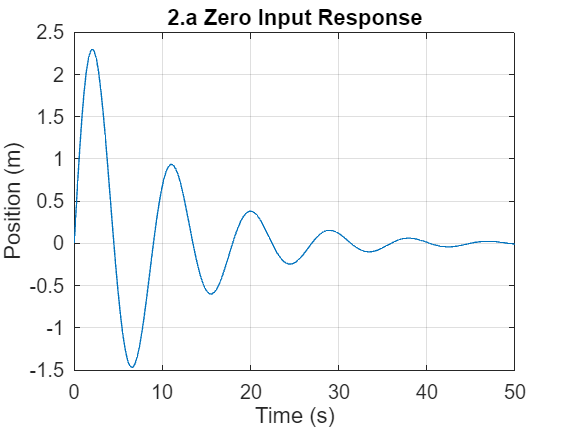


% Plot the result here
figure;
plot(t, x(:,1))
title('2.a Zero Input Response')
grid on
xlabel('Time (s)')
ylabel('Position (m)')

(b) Given the state-space model of the mass-damper-spring system (i.e., `A`, `B`, `C`, `D`), find out the transfer function and see if it matches that of found in (a).

A = [0 1; -k/m -b/m];
B = [0 1/m]';
C = [1, 0];
D = [0];
% Write down the transfer function below
disp("2,b")

2,b


[num, den] = ss2tf(A, B, C, D, 1); 
Gb = tf(num, den)

Gb =
 
       0.3333
  -----------------
  s^2 + 0.2 s + 0.5
 
Continuous-time transfer function.
Model Properties


(c) Find the zero input response using $y\left(t\right)=Ce^{At} x\left(0\right)$ and compare with the results obtaiined in (a). Refer to the function `expm` to define the exponential.

time = 0:0.1:totalTime;
% Complete the code for output y
y_c = zeros(size(time));
for k = 1:length(time)
    
    y_c(k) =  C * (expm(A * time(k))) * x0;
    
end

% Compare by plotting
disp("2.c")

2.c


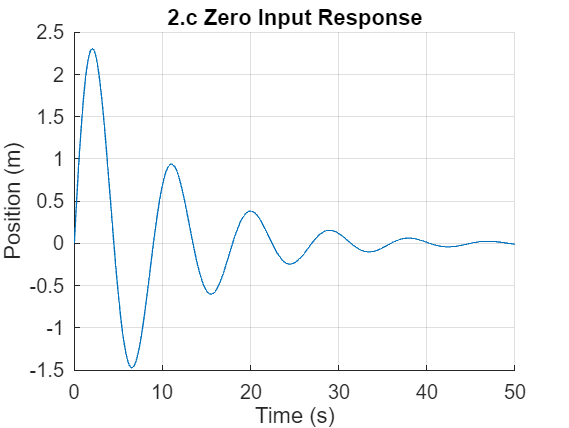

figure;
hold on
title('2.c Zero Input Response')
grid on
plot(time, y_c)
xlabel('Time (s)')
ylabel('Position (m)')

(d) If $C$ is an identity matrix, we will have both the states as outputs. Redefine $C$ and re-simulate the system, and plot both the states against each other.

y_d = zeros(2,length(time));

C = [1, 0;
    0, 1];
for k = 1:length(time)
    y_d(:,k) = C * (expm(A * time(k))) * x0;
end
disp("2.d")

2.d


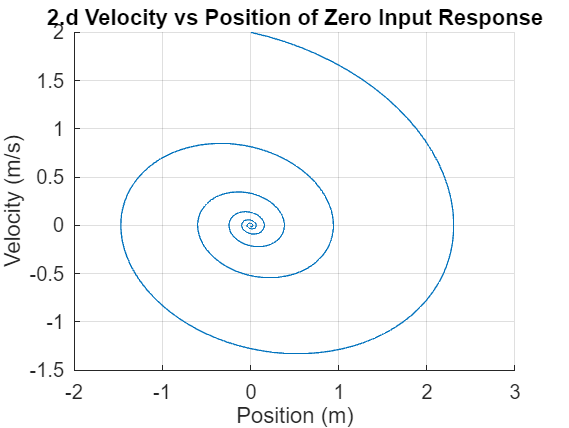

figure;
hold on
title("2.d Velocity vs Position of Zero Input Response")
grid on
plot(y_d(1,:), y_d(2,:))
xlabel('Position (m)')
ylabel('Velocity (m/s)')